## Setup

clear; clc;

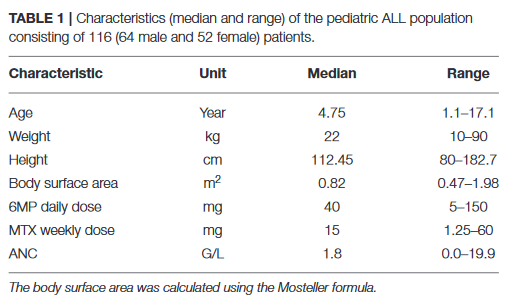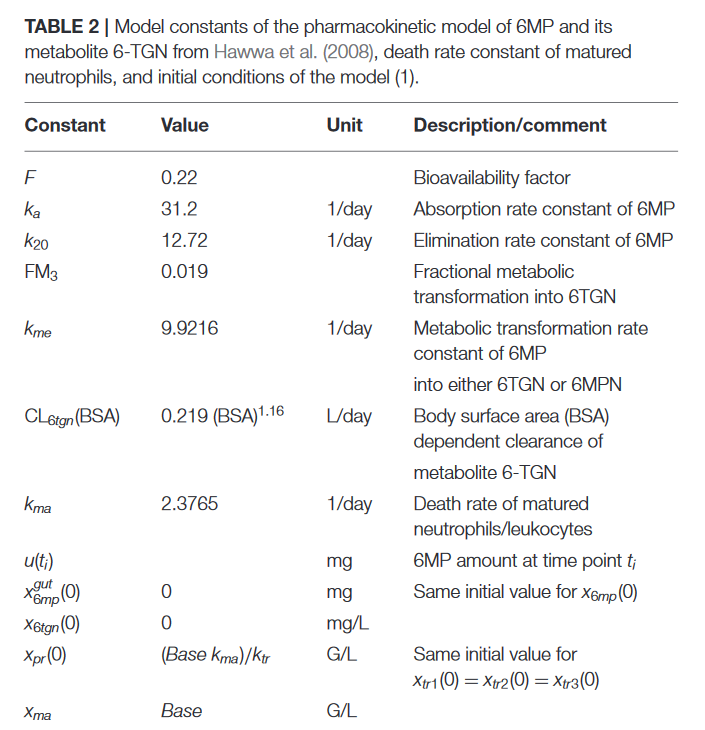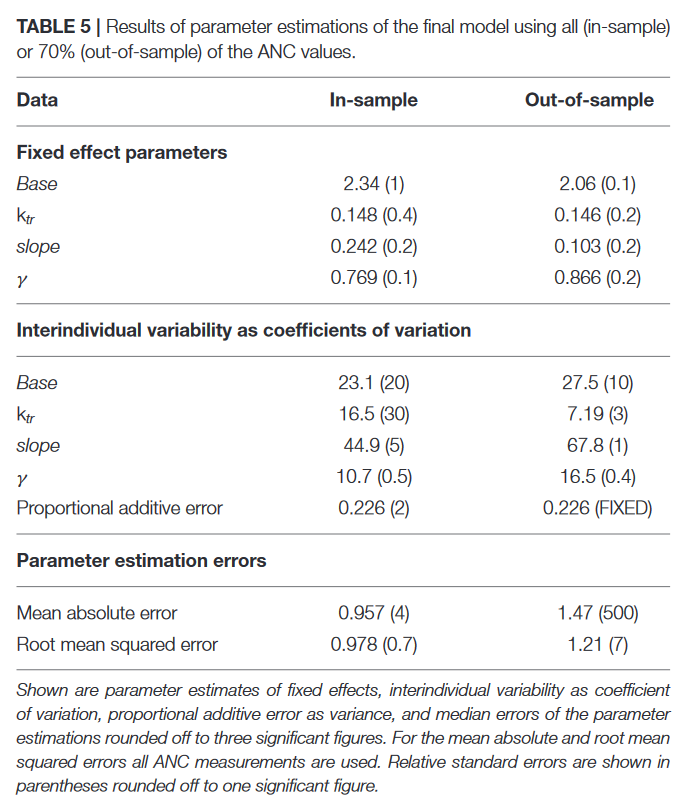

### Model parameters:

syms F k_a k_20 FM_3 k_me CL_6tgn k_ma
syms Base k_tr slope gamma BSA

x_target = 1.5; % Neutrophil concentration, units of G/L
ubar = k_20*CL_6tgn/(slope*FM_3*k_me*F)*(1 - (x_target/Base)^gamma);

xbar_4 = (1-slope*FM_3*k_me*F*ubar/(CL_6tgn*k_20))^(1/gamma)*(Base*k_ma/k_tr);
x_eq = [F*ubar/k_a; F*ubar/k_20; FM_3*k_me*F*ubar/(CL_6tgn*k_20); xbar_4; xbar_4; xbar_4; xbar_4; (1-slope*FM_3*k_me*F*ubar/(CL_6tgn*k_20))^(1/gamma)*Base];

symbols(1,:) = [F, 0.22];
symbols(2,:) = [k_a, 31.2];
symbols(3,:) = [k_20, 12.72];
symbols(4,:) = [FM_3, 0.019];
symbols(5,:) = [k_me, 9.9216];
symbols(6,:) = [CL_6tgn, 0.219*BSA^1.16];
symbols(7,:) = [k_ma, 2.3765];
% Patient-specific parameters:
symbols(8,:) = [Base, 2.34];
symbols(9,:) = [k_tr, 0.148];
symbols(10,:) = [slope, 0.242];
symbols(11,:) = [gamma, 0.8490];
% symbols(11,:) = [gamma, 0.769];
symbols(12,:) = [BSA, 0.82];

% Initial condition
x0 = [0; 0; 0; (Base*k_ma)/k_tr; (Base*k_ma)/k_tr; (Base*k_ma)/k_tr; (Base*k_ma)/k_tr; Base];

%% Equilibrium

xbar_8 = 1.5; % Desired ANC

% Calculate average equilibrium dose (ubar) over the uncertainty set
expr1 = @(b) ((xbar_8./b).^pmax.gamma - (xbar_8./b).^pmin.gamma) .* log(xbar_8 ./ b);
ubar_integral = integral(expr1, pmin.Base, pmax.Base);
ubar_ave = CL_6tgn*k_20/(FM_3*k_me*F*(pmax.slope-pmin.slope)) * log(pmax.slope/pmin.slope) * (1 - 1/(pmax.Base-pmin.Base)/(pmax.gamma-pmin.gamma) * ubar_integral);

xbar_4 = k_ma*xbar_8/(pmax.k_tr-pmin.k_tr) * log(pmax.k_tr/pmin.k_tr);
xbar_3 = FM_3*k_me*F*ubar_ave / (CL_6tgn*k_20);

xbar_ave = [F*ubar_ave/k_a; F*ubar_ave/k_20; xbar_3; xbar_4; xbar_4; xbar_4; xbar_4; xbar_8];

### Convenience terms:

f1 = @(x_eq) -k_tr*x_eq(4)*slope*(Base/x_eq(8))^gamma;
f2 = @(x_eq) k_tr*((1-slope*x_eq(3))*(Base/x_eq(8))^gamma - 1);
f3 = @(x_eq) -k_tr*x_eq(4)*(1-slope*x_eq(3))*Base^gamma*gamma*x_eq(8)^(-gamma-1);

### Model Dynamics:

% syms x_eq [8 1]
syms u

J=sym(zeros(8,8));

J(1,1) = -k_a;

J(2,1) = k_a;
J(2,2) = -k_20;

J(3,2) = FM_3*k_me;
J(3,3) = -CL_6tgn;

J(4,3) = f1(x_eq);
J(4,4) = f2(x_eq);
J(4,8) = f3(x_eq);

J(5,4) = k_tr;
J(5,5) = -k_tr;

J(6,5) = k_tr;
J(6,6) = -k_tr;

J(7,6) = k_tr;
J(7,7) = -k_tr;

J(8,7) = k_tr;
J(8,8) = -k_ma;

% simplify(eig(J))

J_sub = vpa(subs(J,symbols(:,1),symbols(:,2)))

$$J\_sub = \left(\begin{array}{cccccccc} -31.2 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 31.2 & -12.72 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0.1885104 & -0.219\,{\mathrm{BSA}}^{29/25} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -1.2583667306638752341470676016159 & 4.5917748078995605780028770985244e-41 & 0 & 0 & 0 & -2.0176485\\ 0 & 0 & 0 & 0.148 & -0.148 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0.148 & -0.148 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0.148 & -0.148 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0.148 & -2.3765 \end{array}\right)$$


vpa(eig(J_sub))

$$ans = \left(\begin{array}{c} -31.2\\ -12.72\\ -0.219\,{\mathrm{BSA}}^{29/25}\\ 0.000011941618215195793917239855450992-0.083177876077319069796569606740374\,\mathrm{i}\\ 0.000011941618215195793917239855450992+0.083177876077319069796569606740374\,\mathrm{i}\\ -0.22199353989905084803147800068309-0.097949154560999451807312478931181\,\mathrm{i}\\ -0.22199353989905084803147800068309+0.097949154560999451807312478931181\,\mathrm{i}\\ -2.3765368034383286955248784783447 \end{array}\right)$$